# Progetto: stabilizzazione, identificazione e controllo MPC di un pendolo inverso su carrello

#include

addpath('./functions');   %sottocartella con funzioni
addpath('./simulink_models'); %sottocartella con simulink

### Prima di cominciare

Nello script precedente [./stabilizzazione.mlx](matlab:open('./stabilizzazione.mlx')), si è trovata empiricamente la reazione di stato che stabilizzasse il sistema nel punto d'equilibrio. 

Il sistema stabilizzato da usare per l'identificazione è il sistema implementato nel modello simulink [./simulink_models/sistema_con_reazione_stato.slx](matlab:open('./simulink_models/sistema_con_reazione_stato.slx')).

Eseguiamo le seguenti istruzioni per non perderci le dipendenze necessarie dal precedente script

%Variabili di sistema
M = 1; m = 1; g = 9.8; L = 0.5; Kd = 10;

%Condizione iniziale 
teta_zero = 0;

%Variabili di circuito e sensori
ritardo_misura = 1e-6;
limite_sup_att = 200;
limite_inf_att = -200;
tau_derivatore = 0.02;               
Gder = tf([1 0], [tau_derivatore 1]);
Ts_sens_x = 0.002;     
Ts_sens_teta = 0.002;
x_noise_power= 1.4576e-09;       
teta_noise_power =  1.6046e-11;   

%k stabilizzante
k1 = -20.3018;
k2 = -86.59;
k3 = 475.2216;
k4 = 409.0522;

### Presentazione del processo di identificazione

Il sistema da identificare sarà:

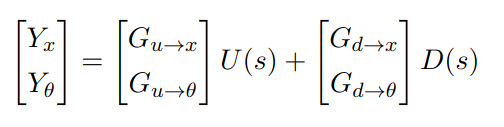

dove u è l'ingresso di controllo del sistema stabilizzato "x_riferimento" e d è il disturbo "dF".

Per conoscere completamente il sistema, dobbiamo quindi fare **4 identificazioni.**

In breve, per ognuna di esse:

- Sceglieremo **un passo di campionamento **dei segnali di PRBS adeguato.

- Generemo i **PRBS **adatti e **simuleremo la risposta del sistema** ad essi, per generare i riferimenti input-output.

- Useremo il System Identification toolbox per trovare dei **modelli polinomiali ARX o ARMAX **che fittino i miei dati di input-output.

Il **flowchart di esecuzione **in breve sarà il seguente:

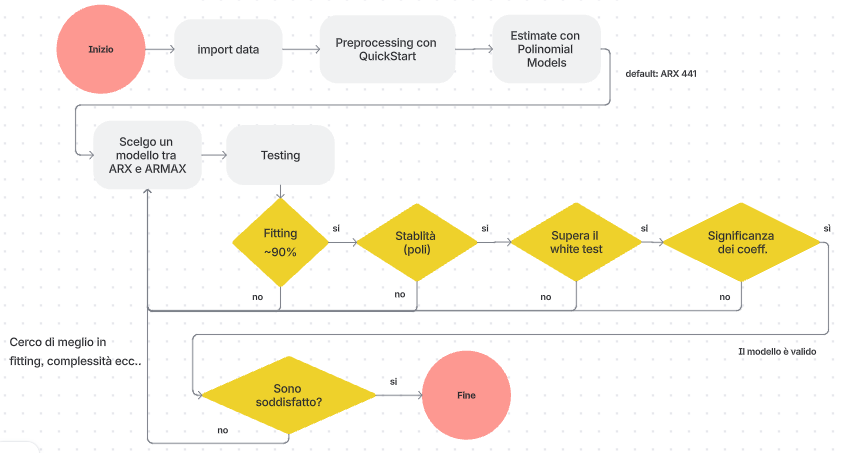

Si notifica che è stato implementato un circuito di validazione per la nostra identificazione, che **confronta il sistema vero con il sistema identificato sottoposti allo stesso ingresso.**

Tale simulink verrà usato alla fine per validare l'intero sistema, ma anche per aiutarsi durante l'identificazione (ad esempio per stabilire la significanza dei coefficienti in casi dubbi).

[./simulink_models/test_identificazione.slx](matlab:open('./simulink_models/test_identificazione.slx'))

### Generazione dei PRBS e simulazione

Per generare il segnale PRBS adatto al nostro scopo, dovremo scegliere:

- Il passo di campionamento (che andrà a fissare il limite in alta frequenza del PRBS): non dev'essere né troppo grande, per non perdere l'informazione del segnale, né troppo piccolo per non campionare anche le componenti rumorose, in alta frequenza.

- L'ampiezza: non dev'essere né troppo grande, che fa destabilizzare il sistema dall'equilibrio, né troppo piccola, per avere un buon rapporto segnale-rumore.

- L'offset: dev'essere la media dell'ingresso d'equilibrio attorno al quale devo fare l'identificazione (NOTA: nel nostro caso è sempre 0)

Dopo una serie di tentativi, si è scelto come passo di campionamento del PRBS:

DeltaT = 0.2;                   %passo campionamento
N_campioni = 500;               %num campioni
T_sim = N_campioni * DeltaT;    %tempo di simulazione

**NOTA: **si è visto che per deltaT più piccoli il fitting diminuisce esponenzialmente, mentre per deltaT più grandi migliora il fitting, ma il confronto con il sistema vero è sempre peggiore (perché il sistema identificato ha una dinamica più lenta).

- **Cattura dei segnali per **$G_{u\to x}$** e **$G_{u\to \theta }$

In questa fase $u=\textrm{PRBS},d=0$

%uso u
id_u_now = true;    %serve a usare il PRBS per la variabile u
        
%setting PRBS
amp = 0.2; offset = 0;
PRBS_input = gen_PRBS(DeltaT, N_campioni, amp, offset);


% sim con ingresso PRBS
simOut = sim('./simulink_models/PRBS_sim', T_sim);


% Salvo i dati
IO_u_x = simOut.IO_x;
IO_u_teta = simOut.IO_teta;

- **Cattura dei segnali per **$G_{d\to x}$ e $G_{d\to \theta }$

In questa fase $u=0,d=\textrm{PRBS}$

%uso d
id_u_now = false;   %serve a usare il PRBS per la variabile d

%setting PRBS
amp = 1; offset = 0;
PRBS_input = gen_PRBS(DeltaT, N_campioni, amp, offset);


% sim con ingresso PRBS
simOut = sim('./simulink_models/PRBS_sim', T_sim);


% Salvo i dati
IO_d_x = simOut.IO_x;
IO_d_teta = simOut.IO_teta;

**NOTA:** "IO_u_x, IO_u_teta, IO_d_x, IO_d_teta" saranno i DataObject da importare nell'IdToolBox, per l'identificazione.

### Identificazione delle 4 funzioni

Nella compilazione di questo script automatizzato, l'user può:

- utilizzare la funzione appena trovata ed estratta nel workspace dall'IdToolbx (nuova identificazione)

- caricare da file di salvataggio la funzione trovata (vecchia identificazione)

Se hai già trovato tutte e 4 le funzioni e vuoi leggerle da file, spunta il seguent checkbox ed esegui questa sezione.

Se vuoi gestire singolarmente i vari casi, lasciala senza spunta e vai al codice corrispondente.

leggi_da_file = true;

I modelli trovati saranno salvati nella cartella:

folder_path = "id_models";

**Nota: **sarà documentato soltanto il primo caso, in quanto ciò che diremo varrà per tutti gli altri (a meno di novità che saranno segnalate e discusse).

    `1. ``Identificazione di `$G_{u\to x}$

CONSIDERAZIONI:

- Da questa tabella, capiamo che **il miglior modello è ARX 341 **in quanto aumentando il numero di coefficienti di a e di b, ottengo coefficienti senza significato che non aumentano il fitting a discapito invece della complessità.

- Il coefficiente **a2 dubbio** è stato testato al simulatore. Se azzerato, il modello si comporta in modo totalmente differente dal modello con a2 di default (che somiglia più al sistema vero), denotando che a2 è significativo

- Il passaggio all'ARMAX o all'ARX 551 non migliora di molto il fitting a discapito di un aumento di complessità, anzi peggiora il test di bianchezza, segno che stiamo sbagliando il modello (probabilmente andiamo in **overfitting**).

- ARX 442 diminuisce il fitting rispetto al 441, denotando che il termine u(k-1) è significativo nella stima

- Il fatto che il modello non rispetti a pieno il test di bianchezza non è un probema. L'onere della validità sarà lasciato alla simulazione finale e al confronto tra il sistema vero e quello identificato. (VEDI DOPO)

Ecco alcune pictures del processo di scelta.

- Si noti qui il grado di fitting delle varie risposte

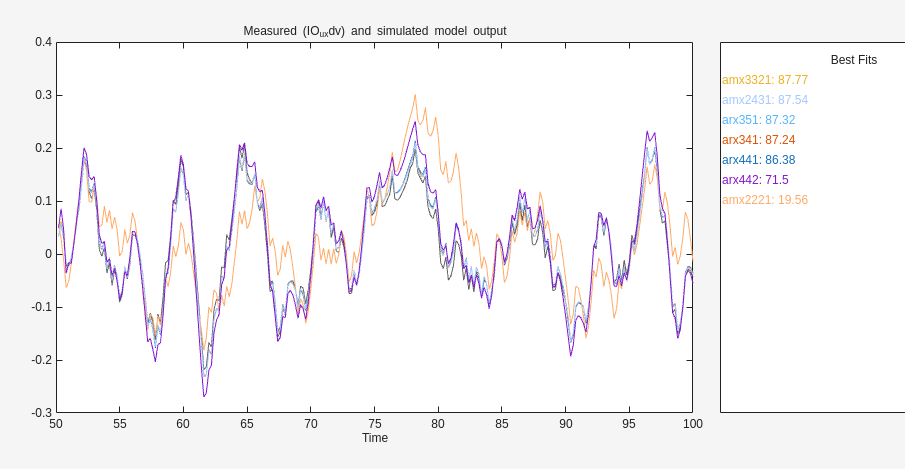

- Si noti qui la stabilità di tutte le soluzioni (poli dentro cerchio unitario)

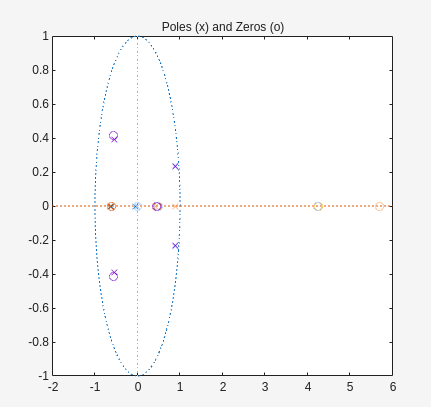

- Si noti qui i test di bianchezza (95%) dei 3 modelli ARX (20 campioni)

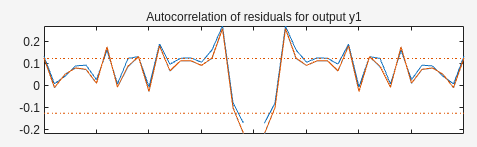

- Si noti qui i test di bianchezza (95%) dei modelli ARMAX (20 campioni): peggiore rispetto agli ARX

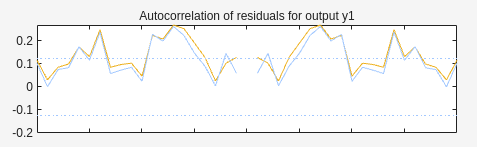

- Si noti qui la non significanza di a4 nell'ARX441: $0\in \left\lbrack 0\ldotp 022\pm 3\cdot 0\ldotp 014\right\rbrack$

- Si noti qui la non significanza di b5 nell'ARX351: $0\in \left\lbrack 0\ldotp 00013\pm 3\cdot 0\ldotp 0013\right\rbrack$

- Si noti qui l'importanza di a2 nel modello ARX 341 scelto, con la stessa simulazione posto a2 di default e a2=0

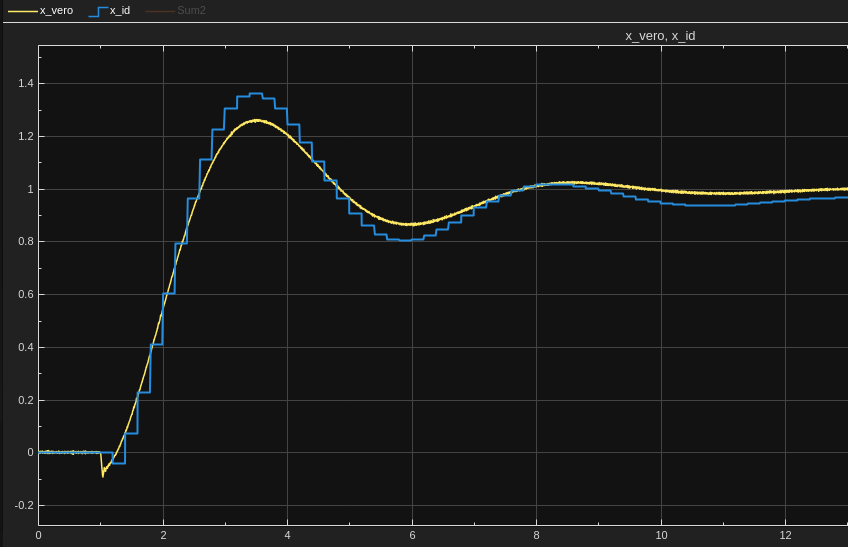

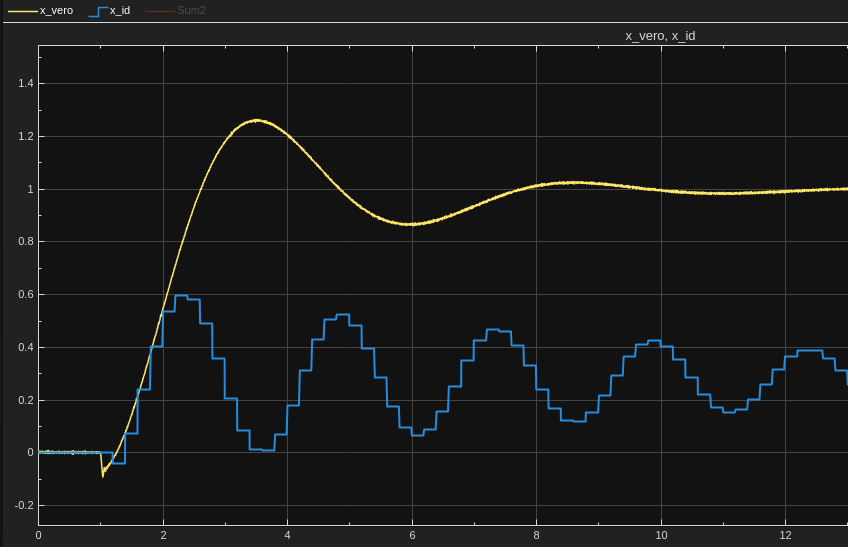

Procedo alla gestione:

file_path_name = folder_path + '/sysid_u_x.mat';

if (~leggi_da_file)  %nuova simulazione, uso e salvo quella appena trovata

    %NOTA: 
    % SI PRESUME L'UTENTE ABBIA ESPORTATO IL MODELLO DAL TOOLBOX
    % Nel mio caso ho esportato "arx341"
    model = arx341; %metti qui il nome del tuo modello

    %estraggo paramtri e definisco la funzione
    [A, B, C, Ts] = extract_from_model(model);
    G_u_x = filt(B, A, Ts)

    %salvo modello in file
    save(file_path_name, 'A', 'B', 'C', 'Ts', 'G_u_x');
    display("overwritten file " + file_path_name);
else 
    load(file_path_name); 
end


    `2. ``Identificazione di `$G_{u\to \theta }$ 

CONSIDERAZIONI:

- La scelta tra i modelli provati non può che cadere sull'**ARX 231**, che a parità di fitting è il modello con minore complessità e con completa significanza.

- Qui si è partito da un fitting alto e quindi si è sfoltito il modello per ridurne la complessità il più possibile, finché non ha perso il fitting.

Procedo alla gestione:

file_path_name = folder_path + '/sysid_u_teta.mat';

if (~leggi_da_file)  %nuova simulazione, uso e salvo quella appena trovata

    %NOTA: 
    % SI PRESUME L'UTENTE ABBIA ESPORTATO IL MODELLO DAL TOOLBOX
    % Nel mio caso ho esportato "arx231"
    model = arx231; %metti qui il nome del tuo modello

    %estraggo paramtri e definisco la funzione
    [A, B, C, Ts] = extract_from_model(model);
    G_u_teta = filt(B, A, Ts)

    %salvo modello in file
    save(file_path_name, 'A', 'B', 'C', 'Ts', 'G_u_teta');
    display("overwritten file " + file_path_name);
else 
    load(file_path_name); 
end


    `3. ``Identificazione di `$G_{d\to x}$ 

CONSIDERAZIONI:

- La scelta tra i modelli provati non può che cadere sull'**ARMAX 3321**, che a parità di fitting con il modello ARX 551 è il modello con minore complessità, con completa significanza e supera perfettamente anche il test di bianchezza

Procedo alla gestione:

file_path_name = folder_path + '/sysid_d_x.mat';

if (~leggi_da_file)  %nuova simulazione, uso e salvo quella appena trovata

    %NOTA: 
    % SI PRESUME L'UTENTE ABBIA ESPORTATO IL MODELLO DAL TOOLBOX
    % Nel mio caso ho esportato "amx3321"
    model = amx3321; %metti qui il nome del tuo modello

    %estraggo paramtri e definisco la funzione
    [A, B, C, Ts] = extract_from_model(model);
    G_d_x = filt(B, A, Ts)

    %salvo modello in file
    save(file_path_name, 'A', 'B', 'C', 'Ts', 'G_d_x');
    display("overwritten file " + file_path_name);
else 
    load(file_path_name); 
end


    `4. ``Identificazione di `$G_{d\to \textrm{teta}}$ 

CONSIDERAZIONI:

- La scelta tra i modelli provati non può che cadere sull'**ARX 221**, che a parità di fitting è il modello con minore complessità, con completa significanza e supera perfettamente anche il test di bianchezza

- Il fatto che semplificando il modello migliori il test di bianchezza, non può che significare che nei modelli più complessi eravamo in **overfitting.**

Procedo alla gestione:

file_path_name = folder_path + '/sysid_d_teta.mat';

if (~leggi_da_file)  %nuova simulazione, uso e salvo quella appena trovata

    %NOTA: 
    % SI PRESUME L'UTENTE ABBIA ESPORTATO IL MODELLO DAL TOOLBOX
    % Nel mio caso ho esportato "arx221"
    model = arx221; %metti qui il nome del tuo modello

    %estraggo paramtri e definisco la funzione
    [A, B, C, Ts] = extract_from_model(model);
    G_d_teta = filt(B, A, Ts)

    %salvo modello in file
    save(file_path_name, 'A', 'B', 'C', 'Ts', 'G_d_teta');
    display("overwritten file " + file_path_name);
else 
    load(file_path_name); 
end

### ARX stima con minimi quadrati 

L'ARX può essere riscritto in forma di regressione come problema ai minimi quadrati

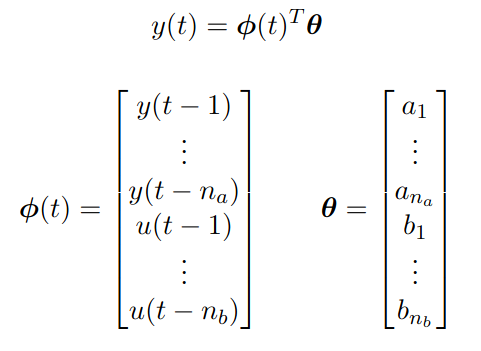

di conseguenza la soluzione ottima è nota:

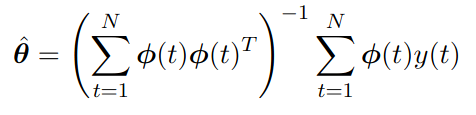

Proviamo a stimare i parametri di $G_{u\to x}$ , identificato con un ARX341

[a_coeff, b_coeff] = ARX_manual_estimation(IO_u_x.OutputData, IO_u_x.InputData, 3, 4);

Ecco il confronto tra il nostro risultato e l'estrazione dei coefficienti dal toolbox

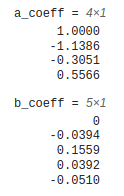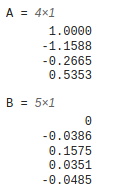

### Validazione dei risultati

La nostra identificazione è completata. Adesso non ci resta che validarla, **confrontando il sistema vero e il sistema identificato in risposta allo stesso ingresso**.

- 1° test: Ingresso a gradino, senza disturbo:

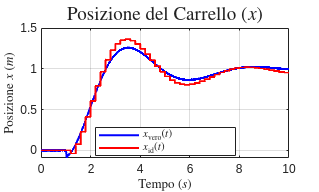

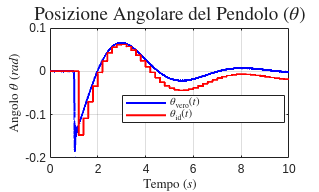

% setto l'input
set_input_simulink_tid(1, 1, 0, 0, 0, 0, 0, 0); %solo gradino amp=1 a stp_time = 1

% eseguo la simulazione
simOut = sim('./simulink_models/test_identificazione', 10); %10 secondi

% plot risposta
plot_id_and_real_x_teta(simOut);

- 2° test: Ingresso sinusoidale, senza disturbo:

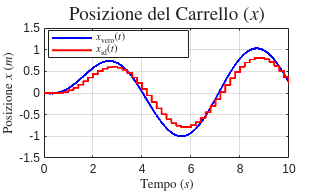

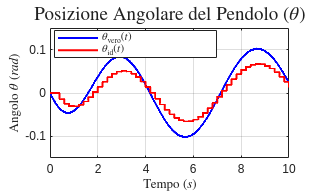

% setto l'input
set_input_simulink_tid(0, 0, 1, 0.5, 0, 0, 0, 0); %solo sin amp=0.5 e frq = 1Hz

% eseguo la simulazione
simOut = sim('./simulink_models/test_identificazione', 10); %10 secondi

% plot risposta
plot_id_and_real_x_teta(simOut);

- 3° test: Ingresso nullo, disturbo a gradino:

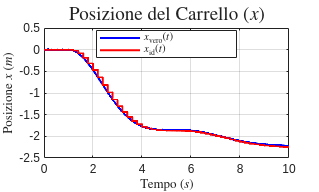

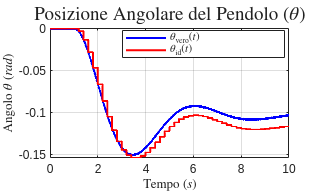

% setto l'input
set_input_simulink_tid(0, 0, 0, 0, 1, 1, 0, 0); %solo d step amp=0.1 e stptime=1

% eseguo la simulazione
simOut = sim('./simulink_models/test_identificazione', 10); %10 secondi

% plot risposta
plot_id_and_real_x_teta(simOut);

- 4° test: Ingresso nullo, disturbo impulsivo:

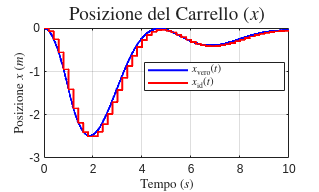

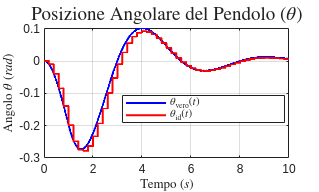

% setto l'input
set_input_simulink_tid(0, 0, 0, 0, 0, 0, 1, 3); %solo d imp durata 1s e amp=3

% eseguo la simulazione
simOut = sim('./simulink_models/test_identificazione', 10); %10 secondi

% plot risposta
plot_id_and_real_x_teta(simOut);

- 5° test: disturbo impulsivo in alta frequenza:

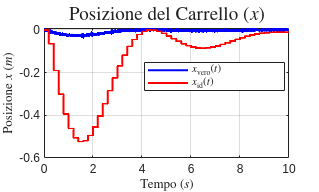

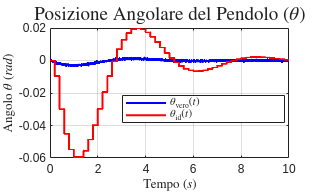

% setto l'input
set_input_simulink_tid(0, 0, 0, 0, 0, 0, 0.01, 3); %solo d imp durata 0.01s e amp=3

% eseguo la simulazione
simOut = sim('./simulink_models/test_identificazione', 10); %10 secondi

% plot risposta
plot_id_and_real_x_teta(simOut);

In questo caso è ovvio che non riesca a replicare il comportamento fisico del sistema, siccome:

- L'identificazione è stata eseguita a basse frequenze, dunque il sistema identificato replica solo il comportamento a bassa frequenza

- Il sistema identificato, è un tempo discreto con un certo tempo di campionamento. Non può che essere imprevedibile nella risposta a segnali con frequenza maggiore di quella di campionamento.

### Conclusioni parte 2

Il sistema è stato identificato con un modello lineare e tempo discreto. Non resta che progettare il controllo su tale modello.

`Cosa fare adesso?  `

Vai alla fase di progettazione del controllo allo script [./controllo.mlx](matlab:open('./controllo.mlx')).

### Studente:

Schettini Francesco (A18000485)

### Esame

IDentificazione e Controllo dei Processi  - prof Cavallo Alberto - aa. 2025-26

### Università

Università degli studi della Campania Luigi Vanvitelli

Laurea magistrale in Ingegneria Informatica  - ramo Automazione

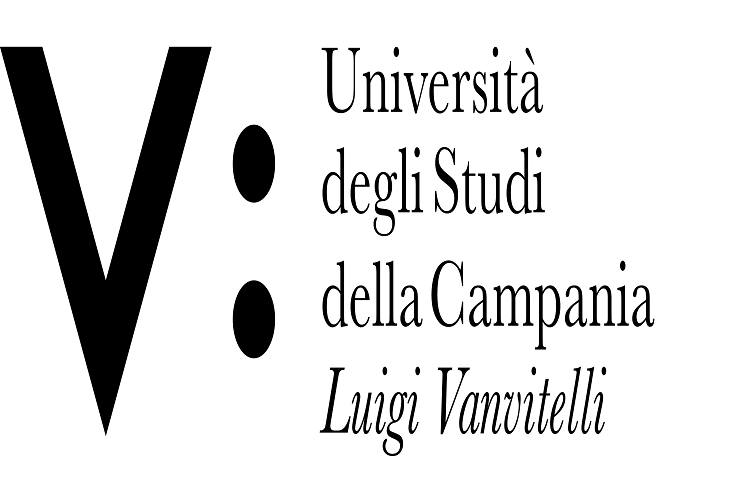

Repo GitHub:

[https://github.com/francesco1203/control_identification_reverse_pendulum_on_cart](https://github.com/francesco1203/control_identification_reverse_pendulum_on_cart)